# Reading Data from the Arduino

(updated 6/9/23)

This script shows how to read data from an Arduino over serial and save it in a usable way. 

*Upload the ArduinoCommunication code to the Arduino before running.*

#### **Select your operating system. **

For a PC, the arduino port will be something like "COM6", and for a Mac, it will be something like "/dev/cu.usbmodem1451"

portType = "COM" % The text pattern to look for (OS dependent)

portType = "COM"

#### Clear previous workspace data

stringArray=string('');

#### Automatically find the serial port the Arduino is connected to

allPorts = serialportlist;  % Creates a list of all available serial ports

% Using the text pattern, this creates a logical array of matching ports
matchingPorts = startsWith(allPorts, portType);   

if any(matchingPorts)                   % If any matches were found,              
    numMatches = sum(matchingPorts);    % Count the number of matches.
    if size(numMatches) > 1             % If multiple matching ports were found, 
        error("Multiple ports found")   % throw an error.
    else                                % If only one match was found,
        port = allPorts(matchingPorts); % that string is the arduino port.
    end
else                                    % If no ports were found,
    error("Port not found")             % throw an error.
end

#### Create a serialport object to talk to the Arduino

ard = serialport(port, 115200);   % Creates a device object (serial port, baud rate)
configureTerminator(ard, "CR/LF") % Sets the line terminator (Carridge Return/ Line Feed)

#### Wait for the Arduino

When the Arduino is ready, it sends "Ready!"

readline(ard); % Read one line of data from the Arduino

#### Tell the Arduino to start sending data

disp('Starting Counting Event in Arduino')

Starting Counting Event in Arduino


writeline(ard,"S"); % Sends the start command to the Arduino (device, string to send)

Read data from Arduino

k = 0; % Array index

% Read the first line of output from the Arduino
newData = readline(ard);
stringArray = split(newData)';

% Read new data until the Arduino signals it's done
while (~strncmp(newData,'Finished',8)) 
    k = k + 1; % k++

    % Save the new line of text to stringArray(k)
    stringArray(k,:) = split(newData)';

    % Read a new line of data from Arduino
    newData = readline(ard);
end


#### **Disconect from the Arduino **

clear ard;

#### **Format the input data**

The data collected is just an array of strings, so in order to do anything useful, we need to convert the strings to numbers

% Change the string array to a cell array using tab delimiter 
data = str2double(stringArray);

% Save data to a .mat file (in case you want to work with it later)
save stepData.mat data

#### Plot the data

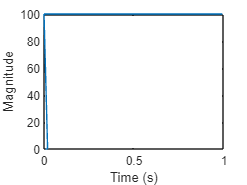

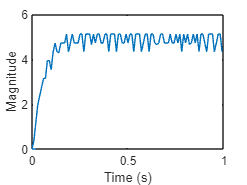

for i=2:size(data,2)
    figure
    plot(data(:,1),data(:,i))
    xlabel('Time (s)')
    ylabel('Magnitude')
end